clear all

t = (0:1:4)'

t =      0
     1
     2
     3
     4



pp=bspline(t) 

pp = struct with fields:
      form: 'pp'
    breaks: [0 1 2 3 4]
     coefs: [4×4 double]
    pieces: 4
     order: 4
       dim: 1


flipud(pp.coefs)

ans =    -0.1667    0.5000   -0.5000    0.1667
    0.5000   -1.0000         0    0.6667
   -0.5000    0.5000    0.5000    0.1667
    0.1667         0         0         0


[1 -2 1; -2 2 1; 1 0 0]

ans =      1    -2     1
    -2     2     1
     1     0     0



timesteps = 20

timesteps = 20


t=linspace(0,1,timesteps+1)'

t =          0
    0.0500
    0.1000
    0.1500
    0.2000
    0.2500
    0.3000
    0.3500
    0.4000
    0.4500


t(end)=[];

M = 0.5*[1 -2 1; -2 2 1; 1 0 0]

M =     0.5000   -1.0000    0.5000
   -1.0000    1.0000    0.5000
    0.5000         0         0



knots = 10

knots = 10

index= [];

output1 = sin(exp(t)+sin(10*t).^2+3*cos(3*t)+1*rand(timesteps,1));
output2= cos(5*t)+1*rand(timesteps,1)

output2 =     1.5698
    1.1887
    1.6200
    1.2729
    0.8144
    0.7023
    0.2558
    0.8148
    0.4446
    0.3200



output_curve = outproduct(output1,output2);

Y = output_curve(:)

Y =    -1.4864
   -1.5667
   -1.4192
   -1.3093
   -1.5395
   -1.3375
   -0.3160
   -1.1092
   -0.8123
   -1.0394


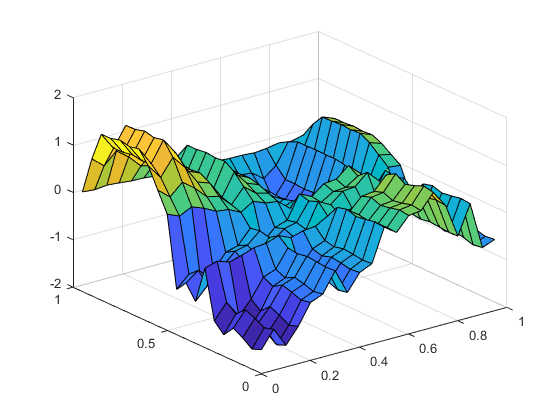

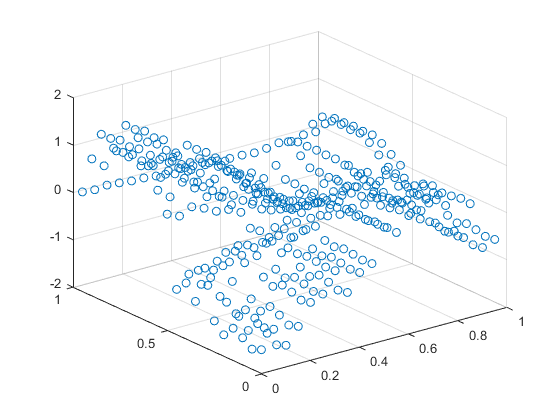


% output_curve(1:80,1:80)=0
surf(t,t,output_curve);

% 
% plot(output1)
% plot(output2)

N=zeros(length(t),knots+2);
B=[]


B =

     []



C=[]


C =

     []




for i=1:length(t)
   index(i)= floor((t(i)*knots+(10*knots*eps)))+1;
    Ntemp = (mod(t(i),1/knots)*knots).^linspace(2,0,3)*M';
%     Ntemp = (t(i)-(index(i)-1)/timesteps/knots).^linspace(2,0,3)*M';
    N(i,index(i):index(i)+2) = Ntemp;
end

for ii= 1:timesteps
    for jj=1:timesteps

N_multi = outproduct(N(ii,:),N(jj,:));

N_T{(ii-1)*timesteps+jj}= [N(ii,:);N(jj,:)];

   B(jj,:)=N_multi(:)';
    end
    C = [C ; B];
end


% -------------------------------------
tic
Theta=zeros((knots+2)^2,1)

Theta =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Pcov =eye((knots+2)^2)*10000

Pcov =        10000           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
           0       10000           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0        


for kk=1:400
    
Phi = C(kk,:);

Pcov = Pcov - (Pcov * Phi'*Phi * Pcov)/(1+Phi*Pcov*Phi');

epsilo(kk) = Y(kk) - Phi * Theta;

K = Pcov*Phi';
Theta = Theta + K *epsilo(kk);

end

toc

Elapsed time is 0.131181 seconds.


% -----------------------------------
tic
P=pinv(C)*output_curve(:);
toc

Elapsed time is 0.006953 seconds.



tol=10^-3
lambda=0.95

d=2
n=(knots+2)
l=1

sigmas= [100000]

PcovT=initP(sigmas,n,d)
PcovT.n
ttcontractkim(PcovT)

XT=initm(l,n,d)
XT.core
XT.n
% ttcontractkim(XT)
lambda=0.5
% ------------------------------------
for epochs=1:2
    
indexez= randperm(400);    
    
    if epochs>1
      lambda=1
%     lambda=0.9+epochs/50
    end
    
for kk=1:400

Phi = N_T{indexez(kk)};
f = contractCPC(XT,Phi);

epsil(kk) = Y(indexez(kk)) - f;

Pc = contractPC(PcovT,Phi,0);
% ttcontractkim(Pc);

cP = contractPC(PcovT,Phi,1);
% ttcontractkim(cP);

cPc = contractCPC(Pc,Phi);

c=squareTN(Pc,cP);
% ttcontractkim(c);

for j=1:size(c.n,1)
c.core{j} = reshape(c.core{j},c.n(j,:));
end

c.core{1} = c.core{1}*(-1/(lambda+cPc));
% ttcontractkim(c);

PcovT = addTN(c,PcovT);

if mod(kk,1)==0
PcovT = roundTN(PcovT,tol);
end

PcovT = reshapeP(PcovT);
PcovT.core{end}= PcovT.core{end}*lambda;

% ttcontractkim(PcovT)

K = contractPC(PcovT,Phi,0);

K.core{1}= K.core{1}*epsil(kk);
% ttcontractkim(K);

XT = addTN(XT,K);

if mod(kk,1)==0
XT = roundTN(XT,tol);
end

% 

end
end

test =ttcontractkim(XT);

y=C*test;
y=C*P;
y=C*Theta;
y=C*test;

norm(test-P)

figure;
hold on
plot(test)
plot(Theta)
% plot(P)
hold off

figure;
hold on
plot(epsilo)
plot(epsil)
hold off

plot(index)
surf(t,t,reshape(y,[timesteps timesteps]))
surf(t,t,output_curve)

surf(1:knots+2,1:knots+2,reshape(P,[knots+2 knots+2]))

norm(reshape(y,[timesteps timesteps])-output_curve)

 surf(t,t,abs(reshape(y,[timesteps timesteps])-output_curve))



[coeff,score,latent] = pca(reshape(P,[knots+2 knots+2]))

plot(latent)
